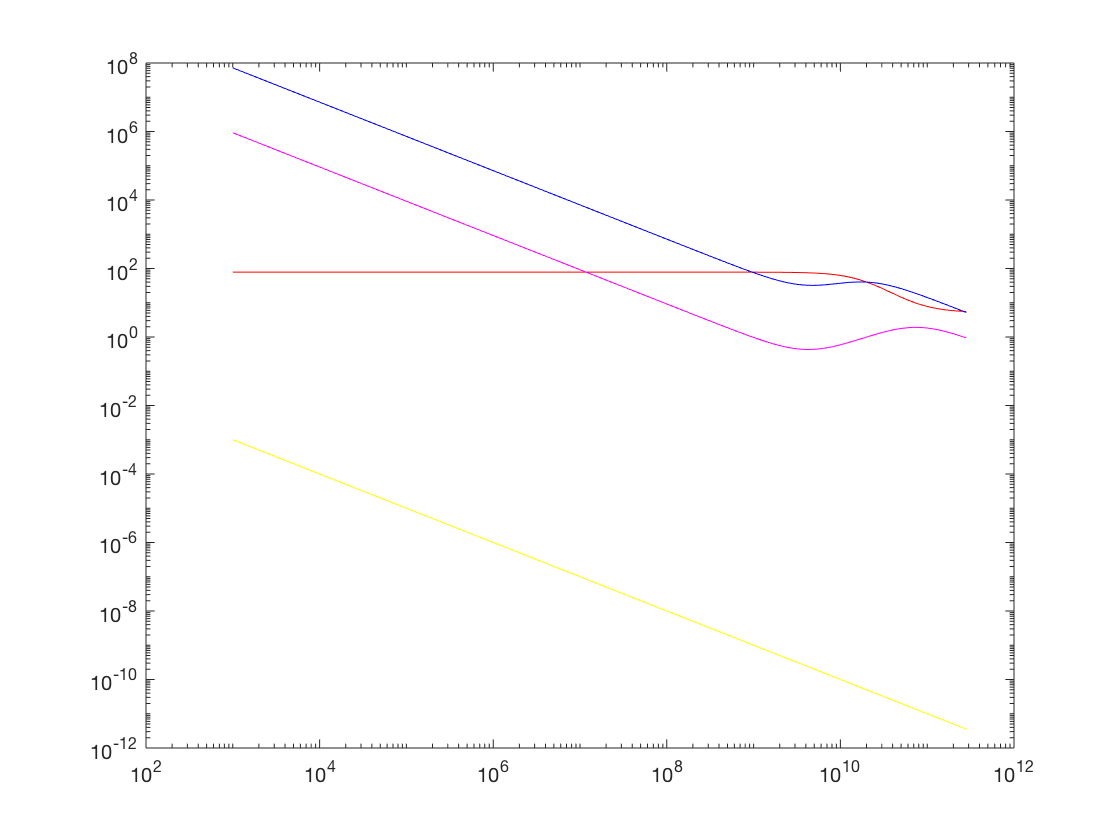

mu = 4*pi*1e-7;
epsilon_0 = 8.85e-12;
f = 10.^(3:0.05:log10(300e9));
omega = 2*pi*f;

[ eps_norm_salt_H20 ]= seawatereps(f);
epsillon_e = real(eps_norm_salt_H20)+1i*imag(eps_norm_salt_H20);
gamma = 1i*omega.*sqrt(epsillon_e.*mu);
norm_lambda = 8.69*real(gamma);
lambda = 2*pi./imag(gamma);
lambda0 = 3e8./f;

loglog(f,real(eps_norm_salt_H20),'r',f,-imag(eps_norm_salt_H20),'b', ...
f,-imag(eps_norm_salt_H20)./real(eps_norm_salt_H20),'m',f,1./f,'y');

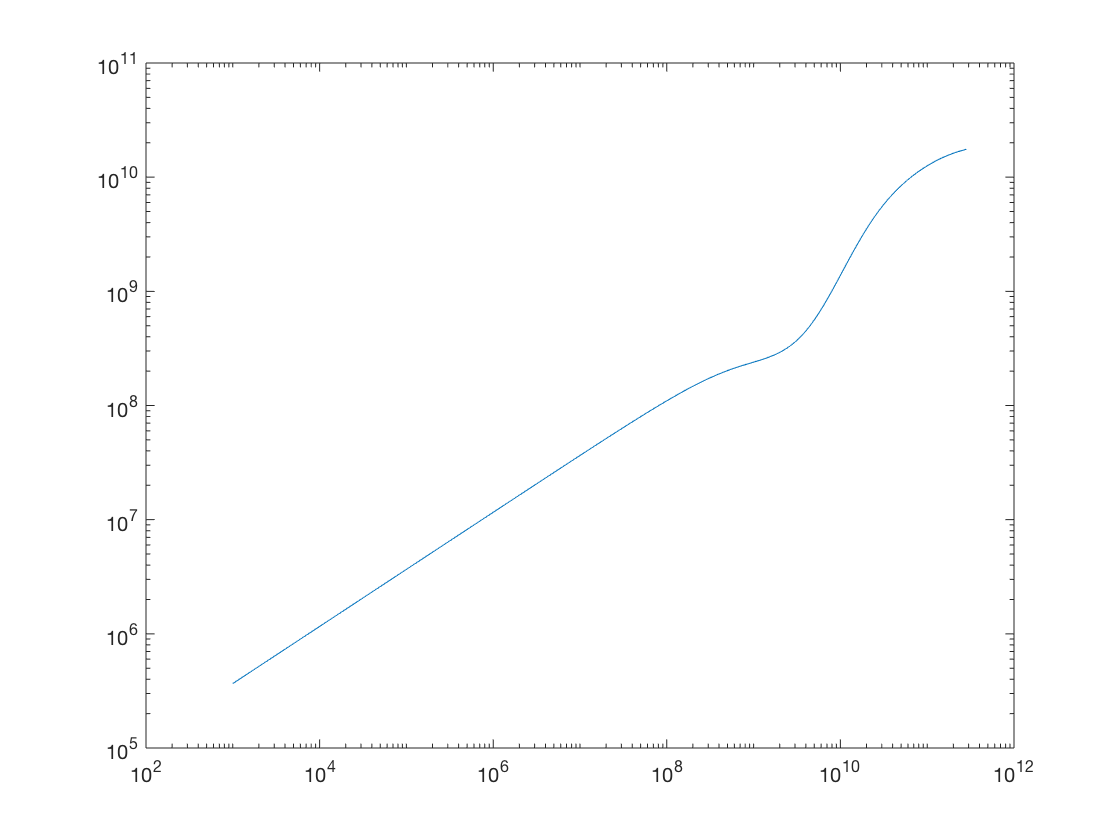

loglog(f,norm_lambda);

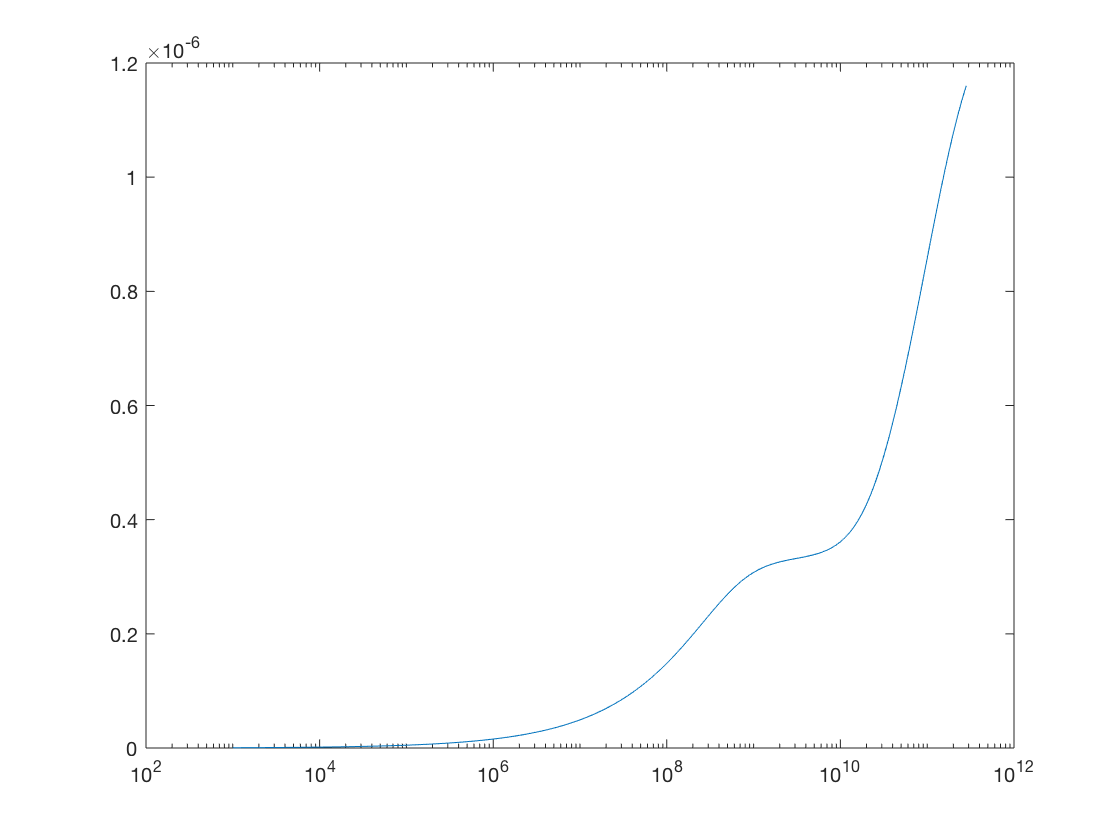

semilogx(f,lambda./lambda0);

function [ eps_norm_salt_H20 ]= seawatereps(f)
eps_norm_salt_H20 = 5.2+(78.3-5.2)./(1+2i*pi*f*8.3e-12)+(4/8.85e-12)./(1i*2*pi*f);
end
